% Parameters
c = 3e8; % Speed of light (m/s)
f0 = 1e9; % Initial frequency of the chirp (Hz)
bandwidth = 1e6; % Chirp bandwidth (Hz)
chirp_duration = 1e-6; % Chirp duration (seconds)
sampling_rate = 1e9; % Sampling rate (samples/second)
t_chirp = 0:1/sampling_rate:chirp_duration; % Time vector for the chirp
object_distances = [100, 105]; % Distances of objects from radar (meters)
reflectivity = [0.8, 0.7]; % Reflectivity factors of the objects (arbitrary units)

% Generate chirp signal
chirp_signal = sin(2 * pi * (f0 * t_chirp + (bandwidth / 2) * t_chirp.^2 / chirp_duration));
chirp_signal = (f0) * ones(size(t_chirp))

chirp_signal = 1.0e+09 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


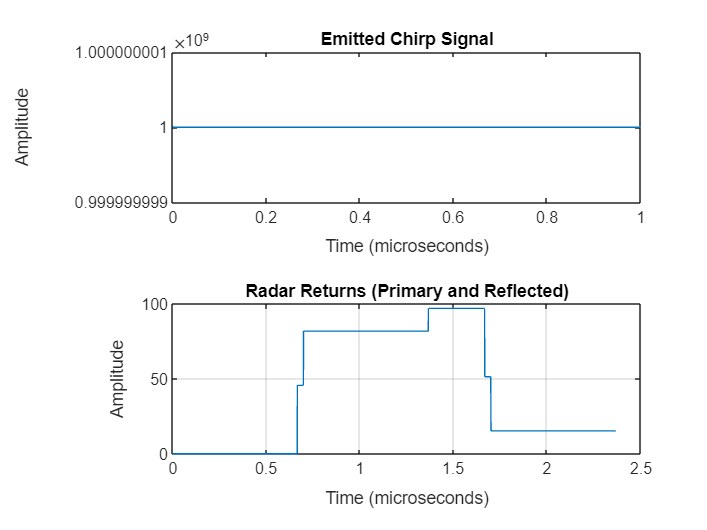



% Time vector for full simulation
max_distance = max(max(object_distances) * 2, sum(object_distances)*2); % Maximum round trip distance
max_time = max(t_chirp) + max_distance / c + 1/sampling_rate; % Maximum round-trip time
time = 0:1/sampling_rate:max_time; % Full time vector for radar returns
radar_signal = zeros(1, length(time)); % Initialize radar signal

% Simulate primary returns
primary_return_signal = zeros([length(object_distances), length(radar_signal)]);
for i = 1:length(object_distances)
    distance = object_distances(i);
    round_trip_time = 2 * distance / c;
    path_loss = (4 * pi * distance / (c / f0))^2; % Use wavelength from f0
    return_power = reflectivity(i) / path_loss;
    delay_samples = round(round_trip_time * sampling_rate);
    % Add scaled chirp signal to the radar signal
    primary_return_signal(i,delay_samples + (1:length(chirp_signal))) = return_power * chirp_signal;
    
    radar_signal(delay_samples + (1:length(chirp_signal))) = ...
        radar_signal(delay_samples + (1:length(chirp_signal))) + return_power * chirp_signal;
end

% Simulate reflected returns
reflected_return_signal = zeros(size(radar_signal));
for i = 1:length(object_distances)
    for j = 1:length(object_distances)
        if i ~= j
            d1 = object_distances(i);
            d2 = object_distances(j);
            total_distance = d1 + d2;
            round_trip_time = 2 * total_distance / c;
            path_loss = (4 * pi * total_distance / (c / f0))^2;
            return_power = (reflectivity(i) * reflectivity(j)) / path_loss;
            delay_samples = round(round_trip_time * sampling_rate);
            % Add scaled chirp signal for reflected return
            reflected_return_signal(delay_samples + (1:length(chirp_signal))) = return_power * chirp_signal;

            radar_signal(delay_samples + (1:length(chirp_signal))) = ...
                radar_signal(delay_samples + (1:length(chirp_signal))) + return_power * chirp_signal;
        end
    end
end

% Plot results
figure;
subplot(2, 1, 1);
plot(t_chirp * 1e6, chirp_signal);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Emitted Chirp Signal');

subplot(2, 1, 2);
plot(time * 1e6, radar_signal);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Radar Returns (Primary and Reflected)');
grid on;

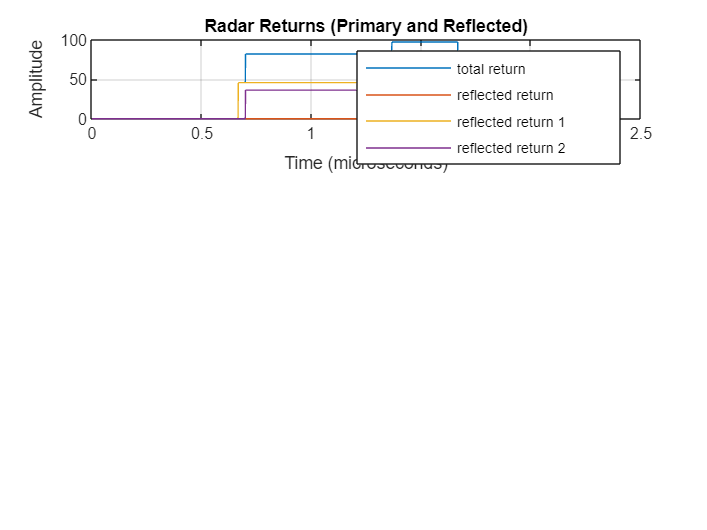


figure
subplot(3, 1, 1);
plot(time * 1e6, radar_signal, "DisplayName","total return");
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Radar Returns (Primary and Reflected)');
grid on;

hold on
subplot(3, 1, 1);
plot(time * 1e6, reflected_return_signal, "DisplayName","reflected return");
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('Radar Returns (Primary and Reflected)');
grid on;

for i = 1:size(primary_return_signal,1)
    hold on
    subplot(3, 1, 1);
    plot(time * 1e6, primary_return_signal(i,:), "DisplayName",sprintf("reflected return %d", i));
    xlabel('Time (microseconds)');
    ylabel('Amplitude');
    title('Radar Returns (Primary and Reflected)');
    grid on;
end

legend